将table文件转变成cell，导出统计数据的统计图：RoA，sensitivity和precision

load("Z:\Result\24-08-29iEMG-US-sEMG联合采集_程瑞佳\matchtable_829_CKC_decomp_filtfilt.mat");

matchtmp=[];seg=[];totalmatch=[];
%目前无对空表的纠正
for i=1:length(matchtable)
    matchtmp=table2array (matchtable{i});
    seg(i)=size(matchtmp,1);
    totalmatch=[totalmatch;matchtmp];
end
header=matchtable{1}.Properties.VariableNames;

matchmat.matchdata=totalmatch;
matchmat.header=header;
matchmat.seg=seg;

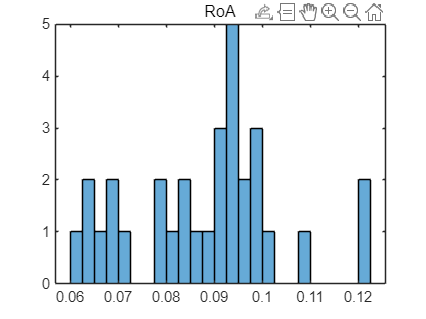

histogram(matchmat.matchdata(:,4),25);title('RoA')

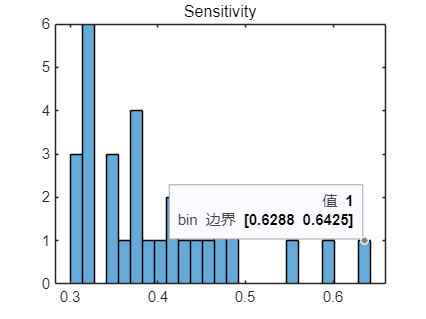

histogram(matchmat.matchdata(:,3),25);title('Sensitivity')

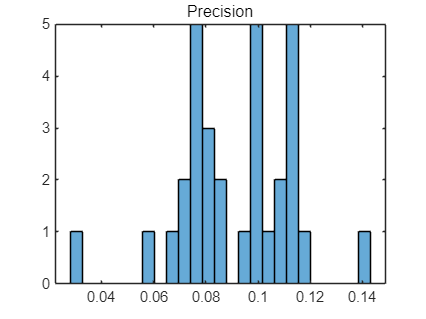

histogram(matchmat.matchdata(:,8),25);title('Precision')